# Figure S8B, S8G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A058_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
                       apcExpressGate(n) = nanmean(dat.apcNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > 0.5 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < 0.1;
        end
      
    end
    S(i).apcExpressGate = apcExpressGate;


end

S8B

conds=[20 11];
colors = [ .5 .5 .5; .6 .9 .2];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 10];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 200000 & yvals >= -200000);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 880

ans = 341

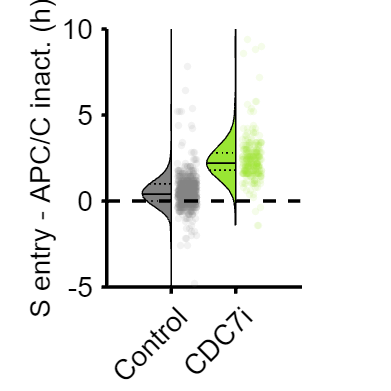


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S entry - APC/C inact. (h)'])


xticklabels({'Control','CDC7i'})
ylim([-5 10])
yticks(-10:5:15)
 xtickangle(45)
 hline(0,'--k')
axis square

set(gca,'fontsize',17,'linewidth',2,'PlotBoxAspectRatio', [.75 1 0.1])




  % print_pdf(['fig_S8B.pdf'])





S8G

conds=[10 7];
colors = [ .5 .5 .5;  .9 0 .8];
POI_align = 3;
ally = [];
groups = [];
timeGate = [ 0 20];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 200000 & yvals >= -200000);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 2237

ans = 245

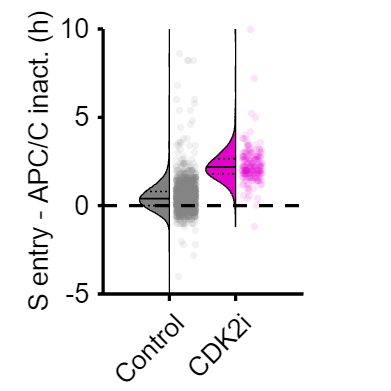


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S entry - APC/C inact. (h)'])


xticklabels({'Control','CDK2i'})
ylim([-5 10])
yticks(-10:5:15)
 xtickangle(45)
 hline(0,'--k')
axis square

set(gca,'fontsize',16,'linewidth',2,'PlotBoxAspectRatio', [.75 1 0.1])


 % print_pdf(['fig_S8G.pdf'])